1. Esboce no seu caderno o espectro do seguinte sinal

𝑦(𝑡) = 10 + 14cos(20𝜋𝑡 − 𝜋/3) + 8cos (40𝜋𝑡 + 𝜋/2)

%% Fmax = 20, pois é a Fmax entre os 3 módulos da função.
Fa = 100; %% >= 40
t = 0:1/Fa:1-1/Fa;

y = 10 + 14*cos(20*pi*t - pi/3) + 8*cos(40*pi*t + pi/2);
N = length(y)

N = 100

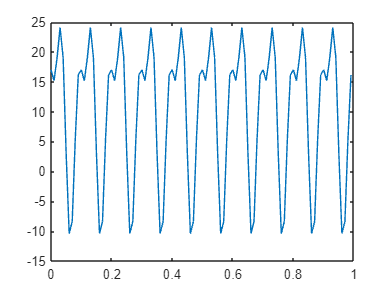

plot(t,y)

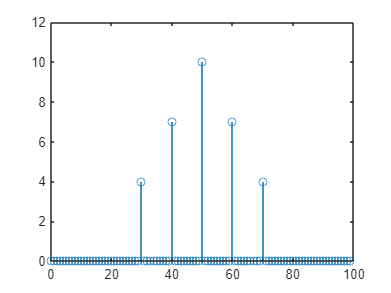


y = fft(y);
y = fftshift(y);

f = (0:N-1)*(Fa/N);
stem(f,abs(y)/N); %% Como o sinal é periodico de periodo

**3. Teste a função desenvolvida no ponto anterior, representando o espectro dos seguintes sinais:**

a) 𝑥(𝑡) = sin (2𝜋𝑡), registado durante 2 e 100 períodos.

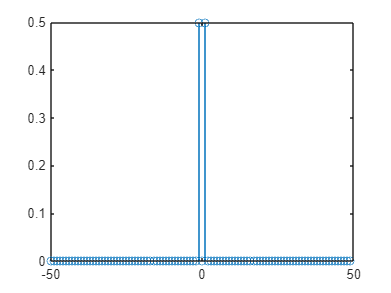

%% Fmax = 1
Fa = 100;
t = 0:1/Fa:1-1/Fa;

x = sin(2*pi*t);
[X, f] = Espetro(x,Fa);
stem(f,abs(X)/N);

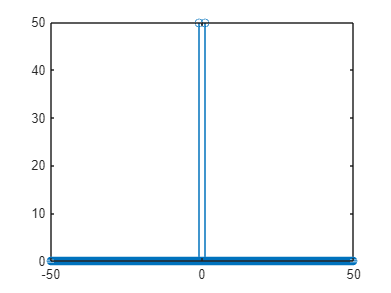


%% Fmax = 1
Fa = 100;
t = 0:1/Fa:100-1/Fa;

x = sin(2*pi*t);
[X, f] = Espetro(x,Fa);
stem(f,abs(X)/N); 

b) 𝑦(𝑡) = sin(10𝜋𝑡) + cos(12𝜋𝑡) + cos (14𝜋𝑡 − 𝜋/4), registado durante 50 seg.

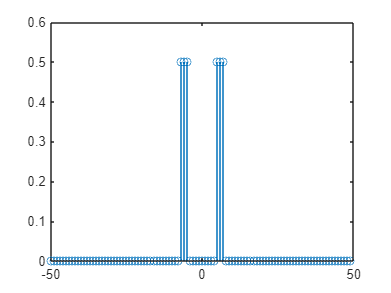

%% Fmax = 7Hz
%% Fy = mmc(5,6,7) = 10
Fa = 100;
t = 0:1/Fa:1-1/Fa;
y = sin(10*pi*t) + cos(12*pi*t) + cos(14*pi*t - pi/4);

[Y, f] = Espetro(y,Fa);
stem(f,abs(Y)/N);

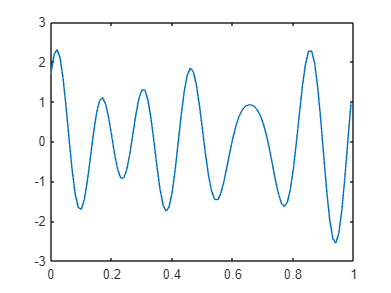


[Y, t] = Reconstroi(Y, f);
plot(t,Y);

c) 𝑦(𝑡) = 10 + 14cos(20𝜋𝑡 − 𝜋/3) + 8cos (40𝜋𝑡 + 𝜋/2), registado durante 100 períodos.

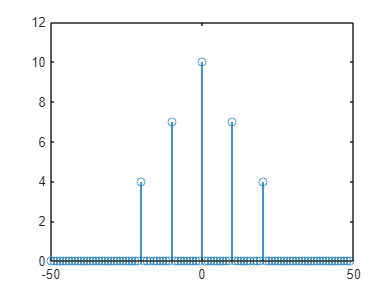

%% Fmax = 20
%% Fy = mmc(10,20) = 10
Fa = 100;
t = 0:1/Fa:1-1/Fa;
y = 10 + 14*cos(20*pi*t - pi/3) + 8*cos(40*pi*t + pi/2);

[Y, f] = Espetro(y,Fa);
stem(f,abs(Y)/N);


[Y, t] = Reconstroi(Y, f);
plot(t,Y);

d) 𝑧(𝑡) – onda quadrada entre 0 e 1, de frequência 1 Hz, registada durante 5 seg.

e) 𝑞(𝑡) - onda triangular entre -1 e 1, de frequência 1 Hz, registada durante 5 seg.

**4. Desenvolva, agora, e com base na função ifft(.) do Matlab, a função Reconstroi que efetua a operação inversa da função desenvolvida na pergunta 2 (i.e., recebendo o vetor 𝐗 da representação em Fourier, reconstrói a sequência de amostras do sinal no domínio do tempo, 𝐱, visualizando, depois, o sinal reconstruído). Teste a função com os dados obtidos nas perguntas anteriores.**

function [X, f] = Espetro(x,Fa)
    N = length(x);    
    x = fft(x);
    X = fftshift(x);
    
    if rem(N,2) == 0
        f = (-N/2:N/2 - 1)*(Fa/N);
    else
        f = (-(N-1)/2:(N-1)/2)*(Fa/N);
    end
end
 
function [x,t] = Reconstroi(X, f)
    N = length(X);
    x = ifft(ifftshift(X));

    dummy = diff(f);
    Fa = dummy(1)*N;
    Ta = 1/Fa;
    t = (0:N-1)*Ta;
end
